# Take the image and segment out the trees

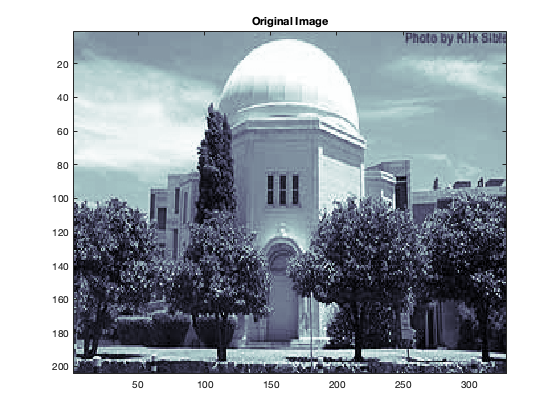

obj = importdata('forclass.mat');
img_original = obj;
h = size(obj,1); % image height 
w = size(obj,2); % image width

mask=obj<90&obj>50;
SE = strel('square',5);
mask = imdilate(mask,SE);
SE = strel('disk',2,8);
mask = imerode(mask,SE);
SE = strel('square',4);
mask = imerode(mask,SE);
SE = strel('disk',2,8);
mask = imdilate(mask,SE);

% Plot Image
figure()
imagesc(img_original)
colormap bone
title('Original Image')

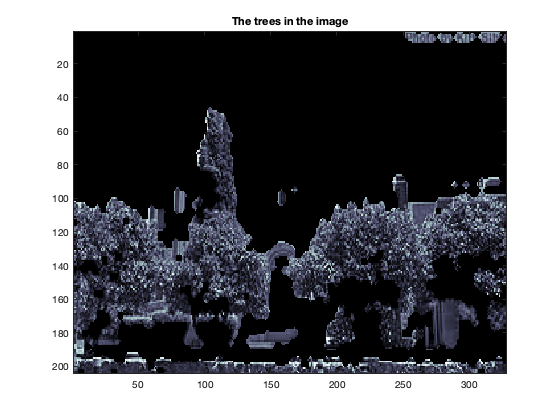


figure()
imagesc(mask.*obj)
colormap bone
title('The trees in the image')